# The example of Find_NRPS_motif_module_pfam_HRL

This script shows how to use this function

1. Assgin all parameters

2. Minimal parameters without seting Pfam_database_path and reference_motif_path in the function

3. Minimal parameters with seting Pfam_database_path and reference_motif_path in the function

## 0. load data

toolboxpath='D:/Shared with me/MATLAB_toolbox';
if exist(toolboxpath,'dir')
    addpath(toolboxpath)
else
    error('Wrong path for MATLAB additional toolbox, please check\n')
end
seq=fastaread('test.fasta');

## 1. Assgin all parameters

If you want to change default value, you need to assgin parameters.

Pfam_database_path='D:/cygwin64/home/74005/Pfam';
reference_motif_path='D:/Shared with me/MATLAB_toolbox/reference_motif';
new_motif={'Aalpha','G','Talpha'};
loop_S_code_judge=1;
length_threshold=0.6;
length_threshold_TE=0.5;
result1 = Find_NRPS_motif_module_pfam_HRL(seq,Pfam_database_path,reference_motif_path,new_motif,loop_S_code_judge,length_threshold,length_threshold_TE);

## 2.Minimal parameters without seting Pfam_database_path and reference_motif_path in the function

If you are not familar with Matlab or this function, you can only set minimal parameters.

Pfam_database_path='D:/cygwin64/home/74005/Pfam';
reference_motif_path='D:/Shared with me/MATLAB_toolbox/reference_motif';
% new_motif={'Aalpha','G','Talpha'};
% loop_S_code_judge=1;
% length_threshold=0.6;
% length_threshold_TE=0.5;
result2 = Find_NRPS_motif_module_pfam_HRL(seq,Pfam_database_path,reference_motif_path);

## 3.Minimal parameters with seting Pfam_database_path and reference_motif_path in the function

User can set Pfam_database_path and reference_motif_path in the function file Find_NRPS_motif_module_pfam_HRL.m

Change Pfam_database_path and reference_motif_path into your path.

It's convenient and user only need input seq. 

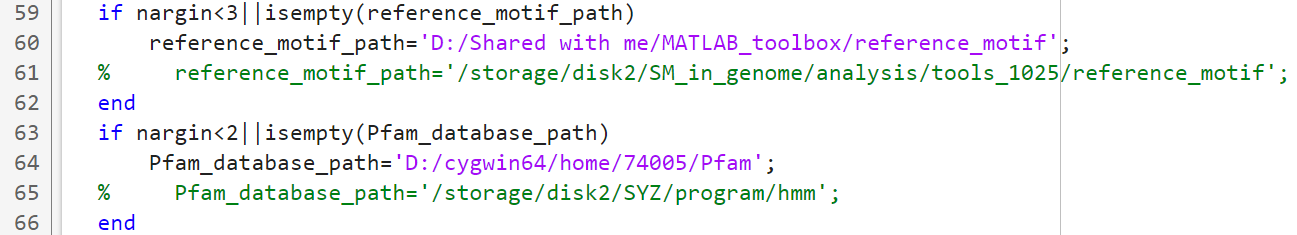

result3 = Find_NRPS_motif_module_pfam_HRL(seq);

## 4.Output

We take result1 as example:

The input sequences are 3 NRPS with known structure (PDB ID: 2VSQ, 4ZXI, 6LTA)

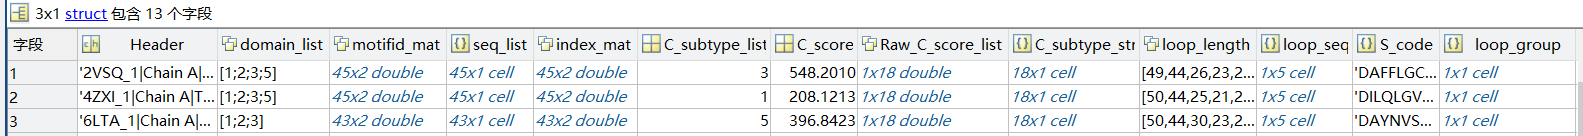

**result** is a n*1 struct with following fields (n is the number of input sequences):

`Header``:the Header in the input ``seq``.`

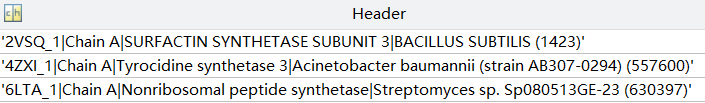

`domain_list``:show the domain compositions of input NRPS sequence. domain id: C:1 A:2 T:3 E:4 Te:5`

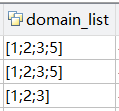

`motifid_mat``:display the motif type in seq_list. motif number: C:7 A:10(+ 0~2) T:1(+ 0~1) E:7 Te:1  details see reference_motif/reference_motif.xlsx`

`The first column is domain. domain id: C:1 A:2 T:3 E:4 Te:5`

`The second column is motif/intermotif. Integer is the index of motif. The float means intermotif.`

`For example: 1.5 means the intermotif between the first motif and the second motif.`

`Especially, 0.5 means the intermotif before the first motif.`

`If no ``new_motif``, the index of motif is equal to motif name for A domain and T domain.`

`A domain: In the second column: 1=A1,2=A2,3=A3,4=A4,5=A5,6=A6,7=A7,8=A8,9=A9,10=A10.`

`T domain: In the second column: 1=T1.`

`Due to new motif (See ``new_motif``), the index of motif may be not equal to motif name.`

`If 'Talpha' is in the ``new_motif``, the all index of T domain will be add one. [1,1] (row) in ``motifid_mat`` will mean Talpha, and [1,2] will mean T1. And so on.`

`In the second column: 1=Aalpha,2=T1`

`If 'Aalpha' is in the ``new_motif``, the all index of A domain will be add one. [1,1] (row) in ``motifid_mat`` will mean Aalpha, and [1,2] will mean A1. And so on.`

`In the second column: 1=Aalpha,2=A1,3=A2,4=A3,5=A4,6=A5,7=A6,8=A7,9=A8,10=A9,11=A10`

`If 'G' is in the ``new_motif``, the index of A6-A10 will be add one. [1,6] (row) in ``motifid_mat`` will mean G-motif, and [1,7] will mean A6. And so on.`

`In the second column: 1=A1,2=A2,3=A3,4=A4,5=A5,6=G-motif,7=A6,8=A7,9=A8,10=A9,11=A10`

`If 'Aalpha' and 'G' are in the ``new_motif``, the index of A1-A5 will be add one and the index of A6-A10 will be add two. [1,7] (row) in ``motifid_mat`` will mean G-motif, and [1,8] will mean A6. And so on.`

`In the second column: 1=Aalpha,2=A1,3=A2,4=A3,5=A4,6=A5,7=G-motif,8=A6,9=A7,10=A8,11=A9,12=A10`

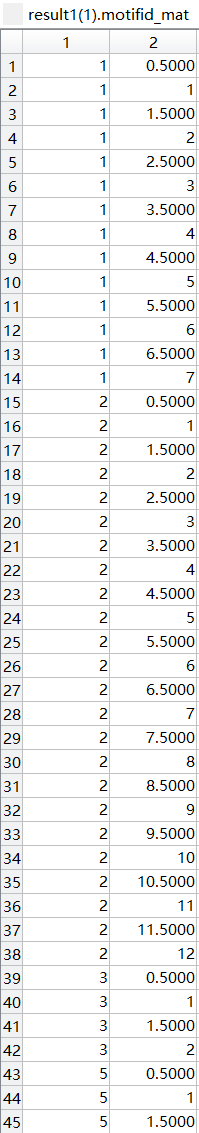

`seq_list``:sequence corresponding with ``motifid_mat``.`

`Each row is the sequence corresponding with the row in the ``motifid_mat``.`

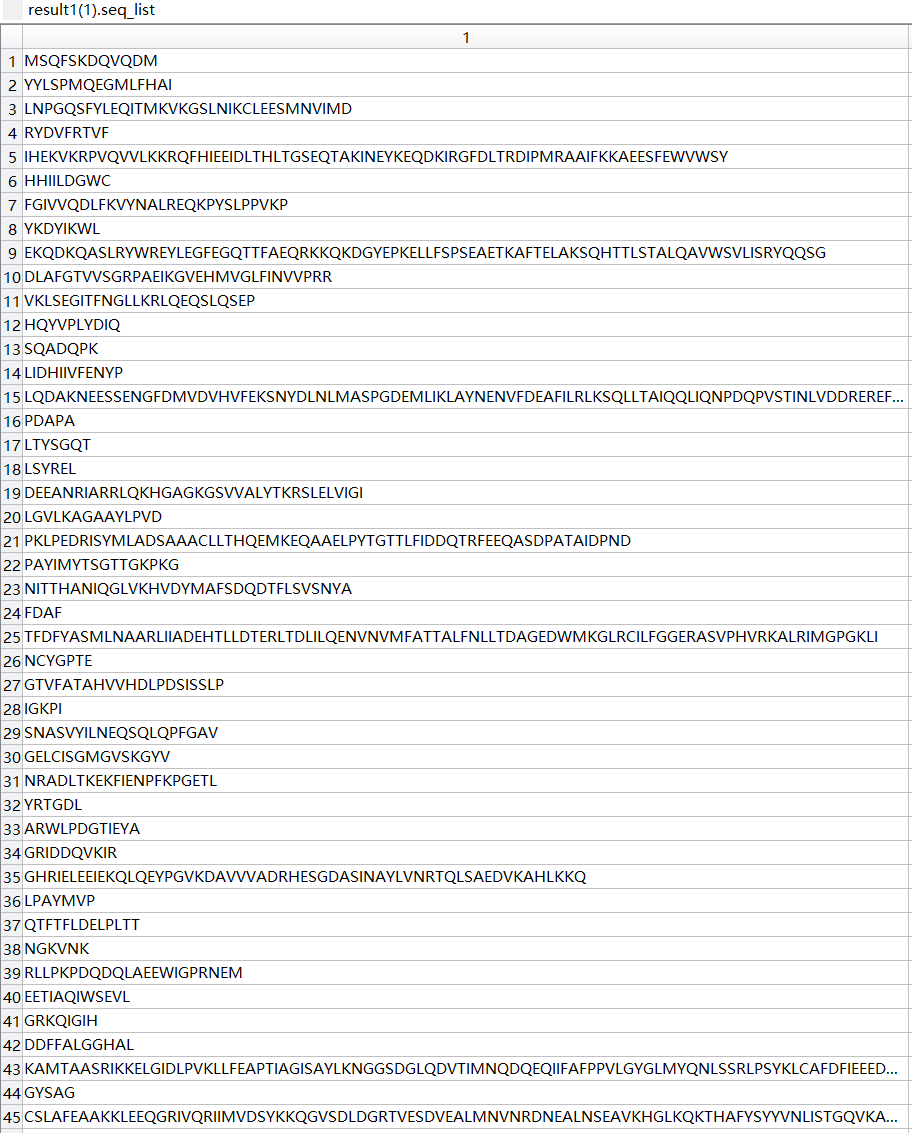

`index_mat``:sequence index for each row in ``motifid_mat``.`

`The index of ``seq_list`` in the input ``seq``.`

`Note:`

`-/*/X in the sequence will be removed, and the index in ``index_mat`` will be influenced (shorter than the original).`

`If domain is incomplete, but the length is more than 0.6* full length, we would put NaN in ``index_mat`` and '' in ``seq_list``.`

`If index is out of range, we would put '1' in ``index_mat``.`

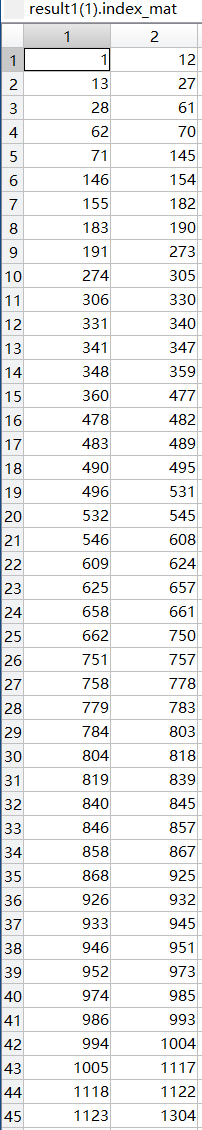

`C_subtype_list``: the most possible domain subtype for each C domain in sequence.`

`The function will predict the subtype of C domain in the input seq.`

`If there is more than one C domain in the input seq, ``C_subtype_list`` will be list.`

`Here, only one number because only one C domain in the input seq `(PDB ID: 2VSQ, 4ZXI, 6LTA).

`The number is the index in ``C_subtype_str``.`

`Therefore, the predicted subtypes of C domains respectively are DCL, LCL and Cyc, which is consistent with references.`

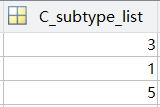

`C_score``: HMM profile alignment score for C subtype. The max score for C domain subtype prediction. If ``C_score`` >= 200, prediction is credible. If ``C_score`` < 200, it should be careful with the results.`

`If the prediction score is low, please check ``Raw_C_score_list``.`

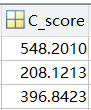

`Raw_C_score_list``: HMM profile alignment score for each C subtype.`

`The full score list of 18 C domain subtypes.`

`Each row is one C domain.`

`C_subtype_str``: string of C subtype in ``C_subtype_list``.`

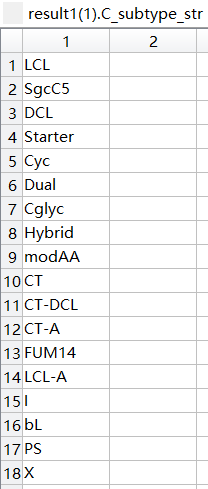

`loop_length``: length of 5 loops:[A3-A4),[A4,S4),[S4,S6),[S6,A5),[A5,G). "[" means inclusion, ")" mean exclusion. [A3-A4) means the length includes A3 but not A4.`

`Each row is one A domain.`

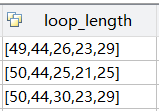

`loop_seq``: sequence of 5 loops.`

`Each row is one A domain.`

**S_code**: Stachelhaus code proposed by Torsten Stachelhaus in 1999.

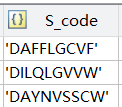

**loop_group**: There are 5 loop groups.

Each row is one A domain.

Loop length and loop group are proposed in our paper. And we found loop group is related with A domain substrate specificity.